# Connecting Data Using Datastore

In this example will be looking at a large amount of vibrationmeasurement data to get started using the new large capabilities found in R2014b. A |datastore| is an object useful for reading collections of data that are too large to fit in memory. It is a repository for multiple files and folders with the same structure and formatting.

## Connecting the data

ds = datastore('Vibration_data\*','Type','Tabulartext','Delimiter','\t','ReadVariableNames',false);         
ds.VariableNames = {'Ch1','Ch2','Ch3','Ch4','Ch5','Ch6','Ch7','Ch8'};

#### Preview the data

a = preview(ds)

a = 8×8 table
     Ch1       Ch2       Ch3       Ch4       Ch5       Ch6       Ch7       Ch8  
    ______    ______    ______    ______    ______    ______    ______    ______
     0.083    -0.027     0.024    -0.095    -0.015    -0.288    -0.273    -0.007
    -0.037    -0.295    -0.002      -0.1    -0.117    -0.037    -0.078    -0.032
     -0.19    -0.027    -0.122    -0.051    -0.071    -0.298     0.081    -0.205
      -0.4    -0.051    -0.093    -0.063    -0.234     -0.11     0.034    -0.122
    -0.205     0.002    -0.083    -0.129    -0.315    -0.264    -0.115    -0.178
     0.044    -0.222    -0.007    -0.325    -0.234    -0.215    -0.166    -0.095
      -0.1    -0.225    -0.129    -0.137     0.017    -0.439    -0

#### Select the variable of interest

If we are only interested in one variable, we can discard the rest

ds.SelectedVariableNames = 'Ch3';

#### Read the chunk

The default size is 20000. You can change the number by 'ReadSize' properties in datasote object. The value can be any positive integers. We can also read one file at a time by change the setting to 'file'.

ds.ReadSize = 'file';
testdata = read(ds);

## Calculating the stadard deviation

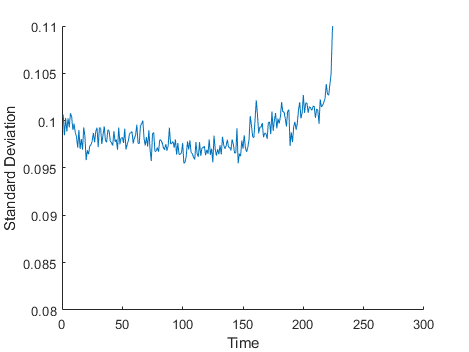

i = 1;
figure;
ax = axes;
xlabel('Time')
ylabel('Standard Deviation')
xlim([0 300])
ylim([0.08 0.11])
h1 = animatedline('Color',[0 0.4470 0.7410]);

while hasdata(ds)

    % Read in Chunk
    dataChunk = read(ds);
    data_std(i) = std(dataChunk.Ch3);
    addpoints(h1, i, data_std(i));
    
    drawnow    
    i = i+1;    
end